Companion software for "Volker Ziemann, *Hands-on Accelerator physics using MATLAB, CRCPress, 2019*" (https://www.crcpress.com/9781138589940)

# TEM-mode in a coaxial waveguide (Section 6.2)

Volker Ziemann, 211113, CC-BY-SA-4.0

**Important:** this example requires the PDE toolbox!

The central conductor present in coaxial waveguides causes the fields to be purely transverse; both longitudinal compenents $E_z$ and $H_z$vanish in the region between the conductors, which forces the transverse fields to obey Equation 6.6 and 6.7. This in turn implies that the fields can be expressed as derivatives $E_x=-\partial\Phi/\partial x$ and $E_y=-\partial\Phi/\partial y$ of a potential $\Phi$, which obeys Laplace's equation $\triangle\Phi=0$ with constant potentials specified on the metallic boundaries. 

In order to solve this problem, we define the domain in which to solve $\triangle\Phi=0$ as the difference between two concentric circles labeled` outer` and `inner,` create the `model` and add the geometry `g` to it. The only difference to previous examples is that we here define the region of interest as the difference between two regions.

clear all; close all;
outer=[1;0;0;0.1]; inner=[1;0;0;0.02];
gd=[outer,inner]; 
ns=char('outer','inner')'; 
sf='outer-inner';     % difference
g=decsg(gd,sf,ns); 
model=createpde(1);
geometryFromEdges(model,g);

After inspecting the `EdgeLabels` and the `SubDomainLabels` we use the first to define the potentials `u =` $\Phi$ on the inner and outer conductors to be 0 and 1, respectively. The Laplace operator in cartesian coordinates is given by the the second derivatives, which we take into account by specifying `c=1` in `specifyCoefficients()`. At this point we can generate the mesh and display it.

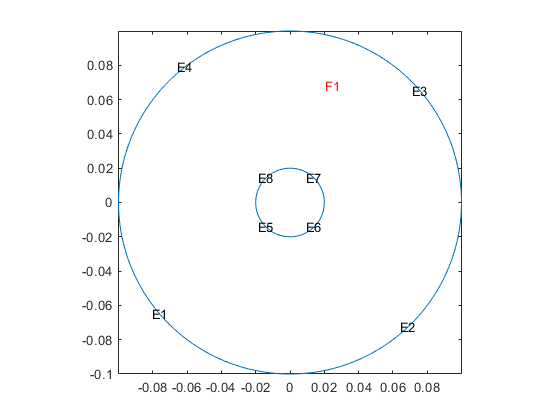

pdegplot(model,'EdgeLabels','on','SubDomainLabels','on'); axis equal

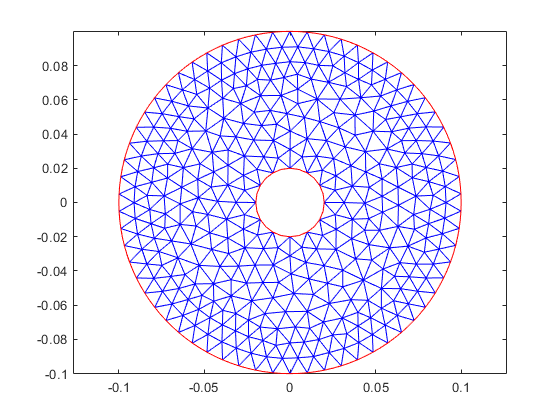

applyBoundaryCondition(model,'Edge',[1:4],'u',0); % outer
applyBoundaryCondition(model,'Edge',[5:8],'u',1); % inner
specifyCoefficients(model,'m',0,'d',0,'c',1,'a',0,'f',0,'Face',1);
generateMesh(model,'Hmax',0.01);
figure; pdemesh(model); axis equal;

Having defined the` model`, we now call `solvepde() `to obtain the potential `u`, which is available as member NodalSolution in the structure` result`, which is retturned from `solvepde()`.  Likewise, the gradients are available and helps us to define the fields` Ex` and `Ey`. From Equation 6.7 we find the magnetic field components `Hx` and `Hy`.

result=solvepde(model); 
Phi=result.NodalSolution;
Ex=-result.XGradients; 
Ey=-result.YGradients; 
Hx=-Ey; Hy=Ex;              % eq. 6.7

The function `meshToPet()` returns information about the points `p`, the edges `e`, and triangles` t`, which we need to display $\Phi$ in the first plot. Subsequent calls to pdeplot() then shows the 

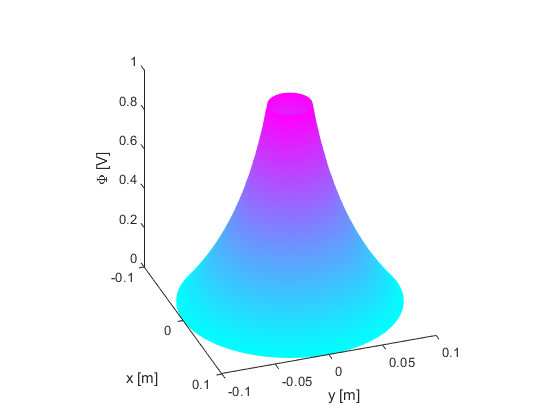

[p,e,t]=meshToPet(model.Mesh);
figure; pdesurf(p,t,Phi); axis square; view([70,30]);
xlabel('x [m]'); ylabel('y [m]'); zlabel('\Phi [V]');

Subsequent calls to `pdeplot()` with the option `flowdata` then produce plots where arrow indicate the direction and magnitude of the electric and magnetic fields.

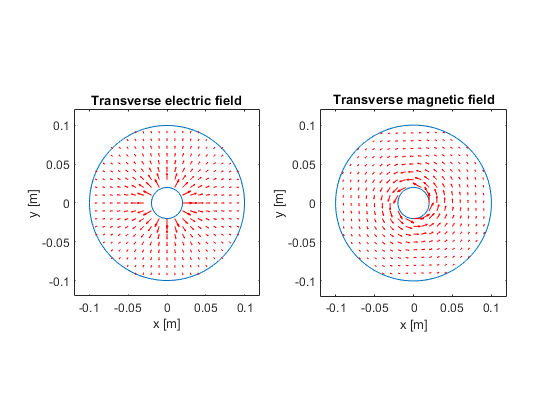

figure
subplot(1,2,1);
pdegplot(model); hold on; pdeplot(model,'flowdata',[Ex,Ey]); 
xlim([-0.12,0.12]); ylim([-0.12,0.12]); axis square; 
xlabel('x [m]'); ylabel('y [m]'); title('Transverse electric field');
subplot(1,2,2); 
pdegplot(model); hold on; pdeplot(model,'flowdata',[Hx,Hy]); 
xlim([-0.12,0.12]); ylim([-0.12,0.12]); axis square; 
xlabel('x [m]'); ylabel('y [m]'); title('Transverse magnetic field');